clc; clear all; close all;

addpath(genpath('.\shared'))

global  ratio file_path_rgb256;
global count time curr_d gt256;
global sensor sate num mu L Qblocks_size flag_cut_bounds dim_cut thvalues;
global  g p;
% global eps;
global coll_flag;

coll_flag = 0;
curr_d = pwd;
sate = 'wv3-8';   % geo,ik,pl, qb, wv2，wv3-8

method = 'lu7';

## start initialization

initialize_sate_RS_MTF();

## start process

% for  num= 1:60   %  batch process
for  num= 15:15
    count = 1 + count

count = 1

## read images and preprocess

%############# need to change here， for reading images. #######

    [rgb256, gt256, mul64, pan256 ] = read_image_sate_RS(num);  % need to change here
% ##################################

## tic start

    tic;
    ORM = gt256;
    img_mul = im2double(mul64);
    P = im2double(pan256);

## initial

    [m,n] = size(P);
    M =imresize(img_mul,size(P),'bicubic');   % 双三次插值算法
    gt_doub = im2double(ORM);  
    
    [I,alpha] = get_I(sate,M, P);
    
    [I_gt,alpha2] = get_I(sate,gt_doub, P);           


    I_ori = zeros(size(mul64,1), size(mul64,2));
    for i= 1:size(M,3)
        I_ori = I_ori + alpha(i)*img_mul(:,:,i);
    end

## original

    M_sum = zeros(size(M,1),size(M,2));
    for i = 1:size(M,3)
        M_sum = M_sum + M(:,:,i);
    end
    M_sum(find(M_sum==0))=eps;
    
    M_rate = zeros(size(M));
    for i=1:size(M,3)
        M_rate(:,:,i) = size(M,3)*M(:,:,i)./M_sum;
    end

## block processing

%% ****** get filter *********************************
    [H,sig,cor_old, P_L] = get_gau_H_RS(P, I);    
    
    switch sate
        case 'ik'  % IKONOS
            g = 0.87;
            
        case 'pl'  % Plaidas
            g = 0.91;

        case 'wv3-8'   % WorldView-3
            g = 1.3;

        case 'qb'   % not used 
            g = 1;

        case 'geo'   % not used 
            g = 1.6;

    end


    IH3_new = get_IH_org(P, I, I_ori);

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

    H2 = get_H_MTF_M(M,sensor,[],ratio);    
    D_In = IH3_new - I;

    co2 = corr2(IH3_new,I);
    coef = (1/(co2-0.05)^2);
    if (strcmp(sate, 'wv3-8'))
        coef1 =  sigmf((co2*co2),[1 -0.6]);     
        coef2 =  sigmf((1-co2*co2),[1 0.01]);  
    end
    if (strcmp(sate, 'pl'))
        coef1 =  sigmf((co2),[1 -0.9]);
        coef2 =  sigmf((1-co2),[1 -0.2]);
    end
    if (strcmp(sate, 'ik'))
        coef1 =  sigmf((co2),[1 0]);
        coef2 =  sigmf((1-co2),[1 0.2]);
    end
    

    for i = 1 : size(M,3)
        ML(:,:,i) = ifft2(fft2(M(:,:,i)).*H2(:,:,i));
        D_m(:,:,i) = M(:,:,i) - ML(:,:,i);
        t(i) = mean2(abs(D_In))/mean2(abs(D_m(:,:,i)));        
        alpha3(i) = estimation_alpha(abs(D_m(:,:,i)),abs(D_In),'global');

        D_t1(:,:,i) = alpha3(i) * D_m(:,:,i);
        D_t2(:,:,i) = t(i) * D_m(:,:,i);
        co = co2;
        D_new(:,:,i) =  coef1 * D_In + coef2* D_t1(:,:,i);
    end
    
    g1 = ones(1,size(M,3));
    for ii = 1 : size(M,3)
        h = M(:,:,ii);
        c = cov(I(:),h(:));
        g1(1, ii) = abs( c(1,2)/var(I(:)));
    end

## get final image

    F_final = zeros(size(M));
    for i = 1:size(M,3)
        F_final(:,:,i) = M(:,:,i)+ g * M_rate(:,:,i).*D_new(:,:,i);
    end
    
    toc

历时 0.598988 秒。


    time(num) = toc;

## show RGB

    F_rgb = zeros(m,n,3);
    for i = 1:3
        F_rgb(:,:,i) =  F_final(:,:,i);
    end
    cd(curr_d);
    % ############## save image here, need to change the path ##################
    save_sate_RS(F_final, M(:,:,1:3), F_rgb, num);
end

## show image

Eval = Evaluation4(ORM,pan256,uint8(F_final*255))

   ||  CC  ||  UIQI  ||  RASE  ||  RMSE  ||  SAM  ||  ERGAS  ||  QNR  ||


Eval =     0.9523    1.7797   12.5152    0.0349    4.7166    3.6150    0.0281


[Q_avg_Segm, SAM_Segm, ERGAS_Segm, SCC_GT_Segm, Q_Segm] = indexes_evaluation(...
    uint8(F_final*255),ORM,ratio,L,Qblocks_size,flag_cut_bounds,dim_cut,thvalues);
Eval2 = [Q_avg_Segm, SAM_Segm, ERGAS_Segm, SCC_GT_Segm, Q_Segm]

Eval2 =     0.9007    4.7469    3.4856    0.9128    0.9106


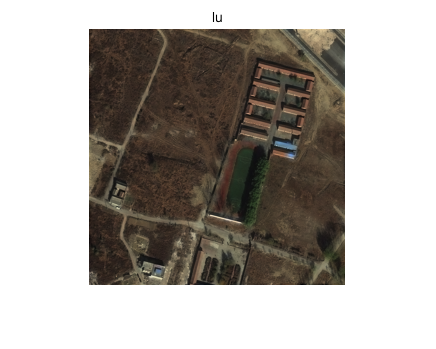


figure,
imshow(F_rgb);
title('lu');

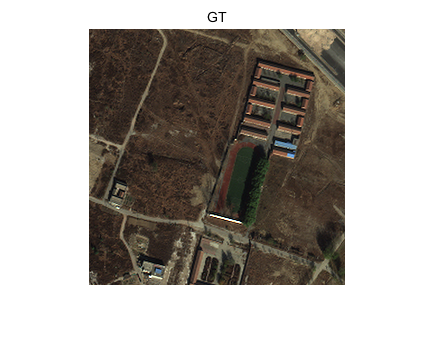

figure,imshow(rgb256);
title('GT');


cd(curr_d);

## write result

T = quality_eval_sate_RS();
cd(curr_d);
writetable(T,strcat('final_result/quality_',method,'_4C_',sate,'_RS_new3.xlsx'),'WriteRowNames',true);

## function iteration